# Process Folder of Images Using Image Batch Processor App

This example shows how to use the **Image Batch Processor** app to process a group of images in the same folder. 

Create a new folder in an area where you have write permission and copy a set of 10 images from the **Image Processing Toolbox** `imdata` folder into the new folder. 

mkdir('cellprocessing');
copyfile(fullfile(matlabroot,'toolbox','images','imdata','AT3*.tif'),'cellprocessing','f');

## Load Images into Image Batch Processor App

Open the **Image Batch Processor** app from the MATLAB® toolstrip. On the **Apps** tab, in the **Image Processing and Computer Vision** section, click **Image Batch Processor ** . 

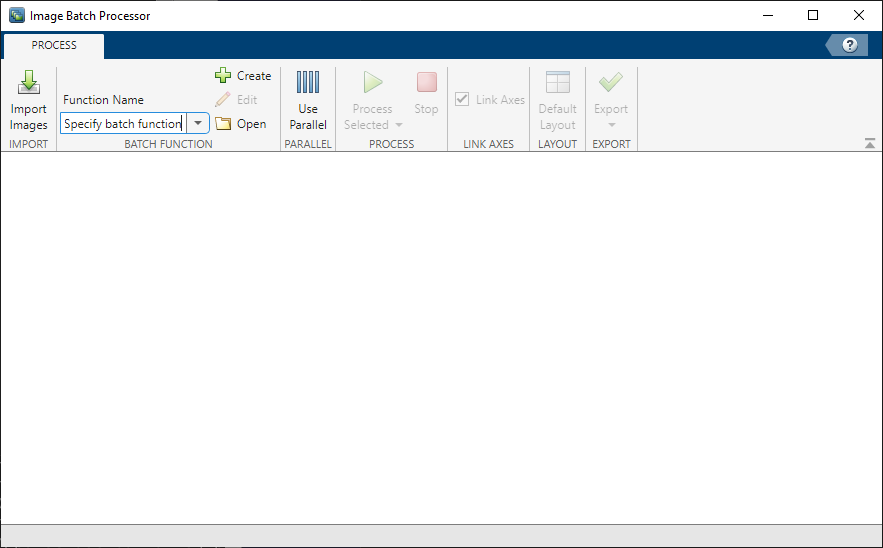

Load images into the app. In the app toolstrip, click **Import Images**. In the Load Images from Folder dialog box, specify the folder containing the images you want to load. For this example, specify the folder that you created in the first step, `cellprocessing`. By default, the app includes images in subfolders. To change this behavior, clear **Include images in subfolders**. Then, click **Load**.

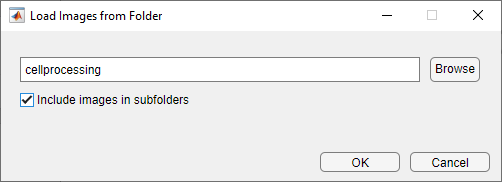

The **Image Batch Processor** app creates thumbnails of the images in the folder and displays them in a scrollable tab in the left pane. The app displays the first selected image (highlighted in blue) in larger resolution in the Input Image tab in the right pane.

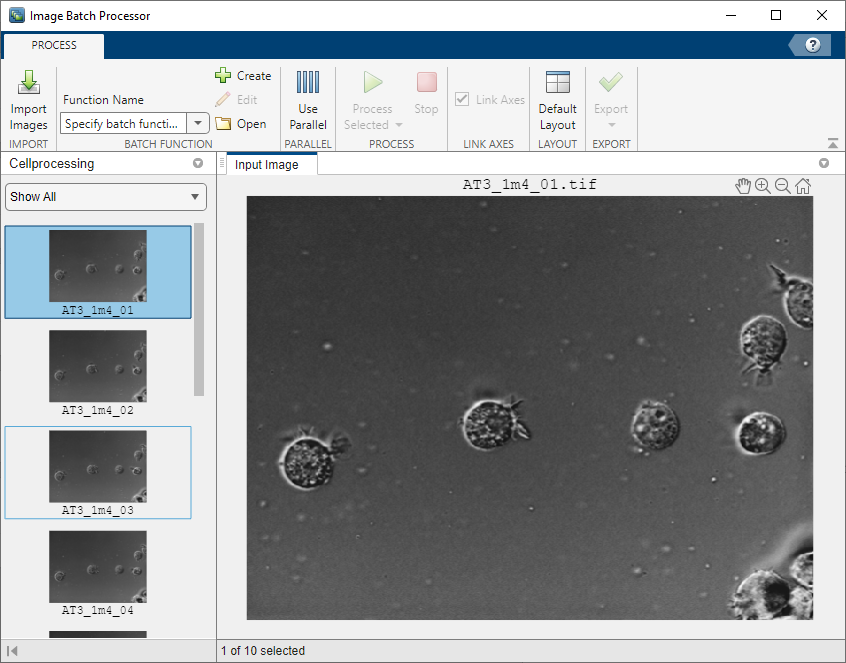

## Specify Batch Processing Function

Specify the name of the function you want to use to process the images in the folder. To specify an existing function, type the name in the **Function** **Name** box in the Batch Function section of the app toolstrip. You can also click the folder icon next to the box to browse and select the function. To create a new batch processing function, click **Create** in the Batch Function section of the app toolstrip. When you do this, the app opens the batch processing function template in the MATLAB® Editor. For this example, click **Create** to create a new function. 

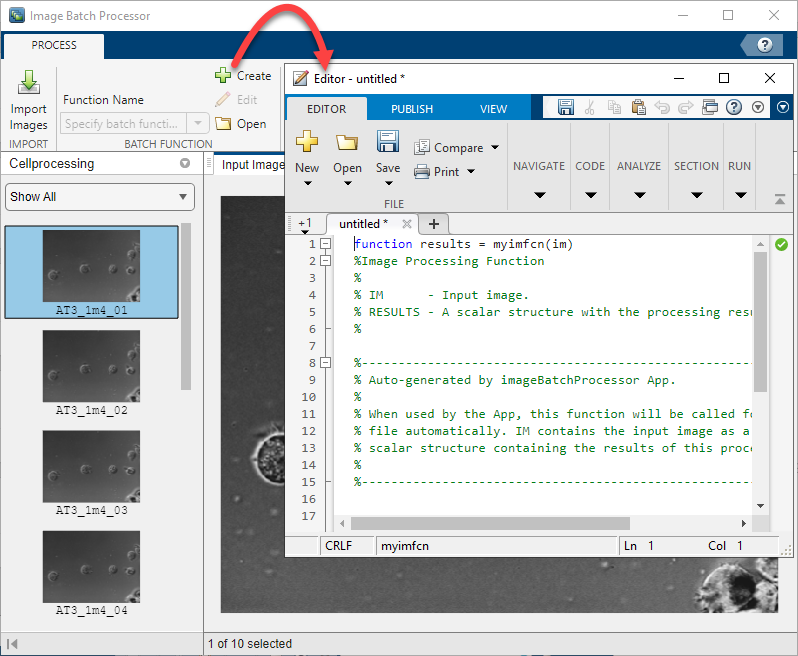

In the batch processing function template, enter code for the new function into the space reserved in the template file and click **Save**. This example uses the default name for the batch processing function, `myimfcn`, but you can specify any name. For this example, the code specifies a function that creates a mask image, calculates the total number of cells in the image, and creates a thresholded version of the original image.

function results = myimfcn(im)
%Image Processing Function
%
% IM      - Input image.
% RESULTS - A scalar structure with the processing results.
%

%--------------------------------------------------------------------------
% Auto-generated by imageBatchProcessor App. 
%
% When used by the App, this function will be called for every input image
% file automatically. IM contains the input image as a matrix. RESULTS is a
% scalar structure containing the results of this processing function.
%
%--------------------------------------------------------------------------

imstd = stdfilt(im,ones(27));
bw    = imstd>30;

thresholdMask = imfuse(im, bw);
[~, n] = bwlabel(bw);

results.bw = bw;
results.thresholdMask = thresholdMask;
results.numCells = n;
end

Save the file. After saving, the app displays the name of this new function in the **Function Name** box on the app toolstrip.

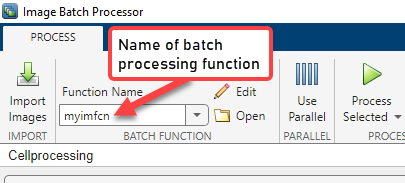

## Process Images Using Batch Processing Function

Test the new function by running the batch processor on one of your images. With one image selected (highlighted in blue), click **Process Selected** to process the selected image. The app displays the results of the processing in a new panel called **Results**. For this example, the app displays the binary mask, a count of the number of objects (cells) in the image, and a thresholded version of the image. 

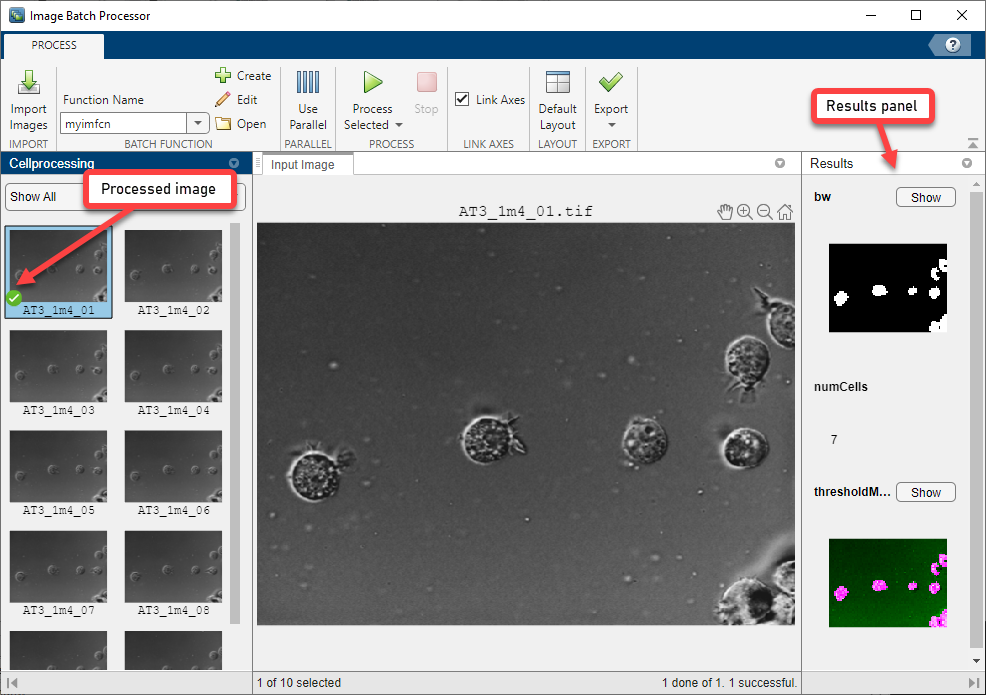

To get a closer view of the image results, click **Show** for that particular result in the **Results **panel. The app open a larger resolution version of the image in a new tab in a bottom-center pane. For this example, view the binary mask results be clicking **Show** for `bw` in the **Results** panel. To explore the results, move the cursor over the image to access the pan and zoom controls. When zooming and panning, the app links the result image to the original image—panning or zooming on one image causes the other image to move as well. If you do not want this behavior, clear **Link Axes** in the app toolstrip.

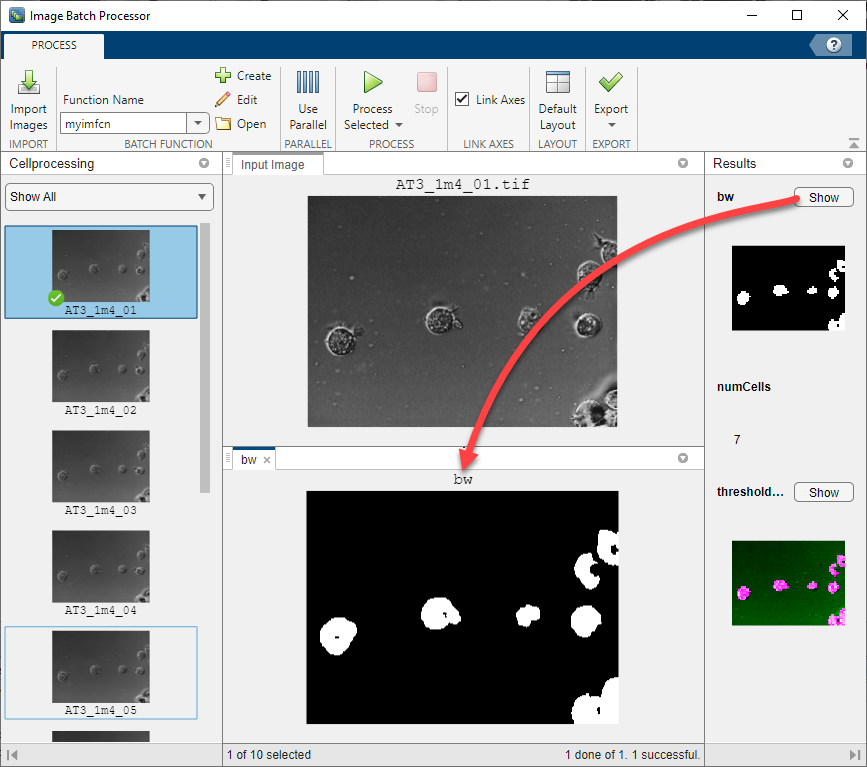

If the results of the test run on one image are successful, then execute the function on all of the images in the folder. To process all the images at once, on the app toolstrip, click **Process Selected **and select **Process All**. To process only a subset of the images, click **Process Selected**. You can select images to process either by pressing **Ctrl** and clicking the desired images or by clicking one image to start, pressing **Shift**, and clicking another image to select all images in between the starting and ending images. If you have Parallel Computing Toolbox™, you can click **Use Parallel** on the app toolstrip to process the images on a local parallel pool. For this example, process all of the images.

The app processes all the images in the specified folder. A filled-in green square next to a thumbnail indicates the app successfully processed that image. The **Results** panel contains the results of the selected image (highlighted in blue). A status bar at the bottom-right of the app reports on the number of images processed.

## Export Processed Images and Processing Pipeline

To save the results, click **Export** to view the options available. You can export results to the workspace or to a file, or you can get the MATLAB® code the app used to generate the results.

Save the results in a workspace variable. On the app toolstrip, click Export and select **Export result of all processed images to workspace** option. In the dialog box that opens, select the results you want to export. A common approach is to export the nonimage results to the workspace and save the images that result from the processing in files. This example saves the cell count along with the name of the input file to the workspace variable `numCells`.

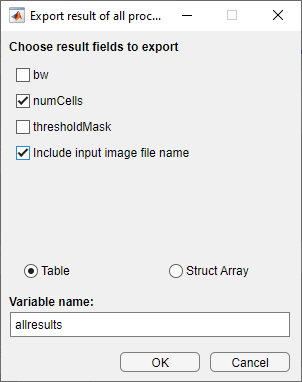

By default, the app returns the results you select in a table named `allresults`. To store the results in a structure instead of a table, select Struct Array in the **Choose format** section of the dialog box. To specify another name for the result variable, change **Variable name** in the dialog box. If you select **Include input image file name**, the app includes the name of the image associated with the results in the structure or table. After specifying exporting details, click **OK**.    

To get the MATLAB® code that the app used to process your files, on the app toolstrip, click **Export** and select the** Generate function**. The app generates a function that accepts the input folder name and the output folder name as input arguments. By default, the function returns a table with the results, but you can choose a structure instead. For image results, you can specify the file format and whether you want the function to write the image to the specified output folder. 

*Copyright 2019 The MathWorks, Inc.*